clear all;
close all;
clc;


## Definindo Função

g = @(t) exp(-t)

g = function_handle with value:
    @(t)exp(-t)



T0 = 1;
f0 = inv(T0);
w0 = 2 * pi * f0;

## Cálculo das Projeções

% Definindo Py e Dy
syms n t
D = 1/T0 * int(g * exp(-j*n*w0*t), t, 0, T0)

$$D = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}$$

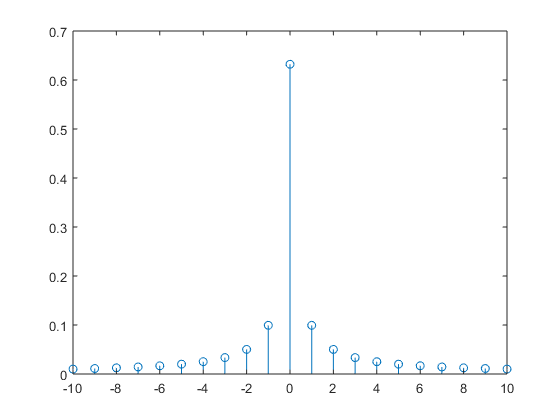


% Determinando os valores numéricos
N = 10;
n = [-N:1:N];

Dn = eval(D);

figure(1)
stem(n*f0,abs(Dn))

## Síntese de Fourier

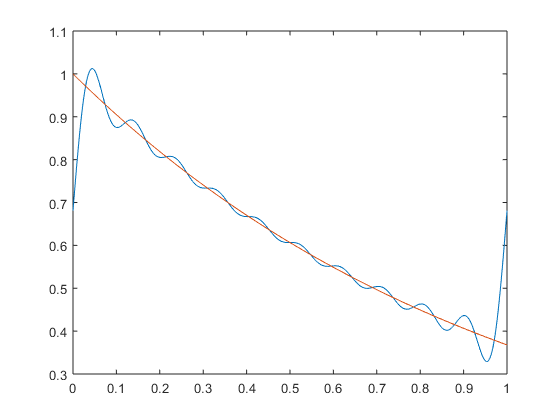

aux = 0;
R = T0/1000;          %%% resolução do sinal no tempo
t = [0:R:T0];

for i=1:2*N+1
    aux = aux + Dn(i)*exp(j*n(i)*w0*t);
end

figure(2)
plot(t,aux,t,g(t))